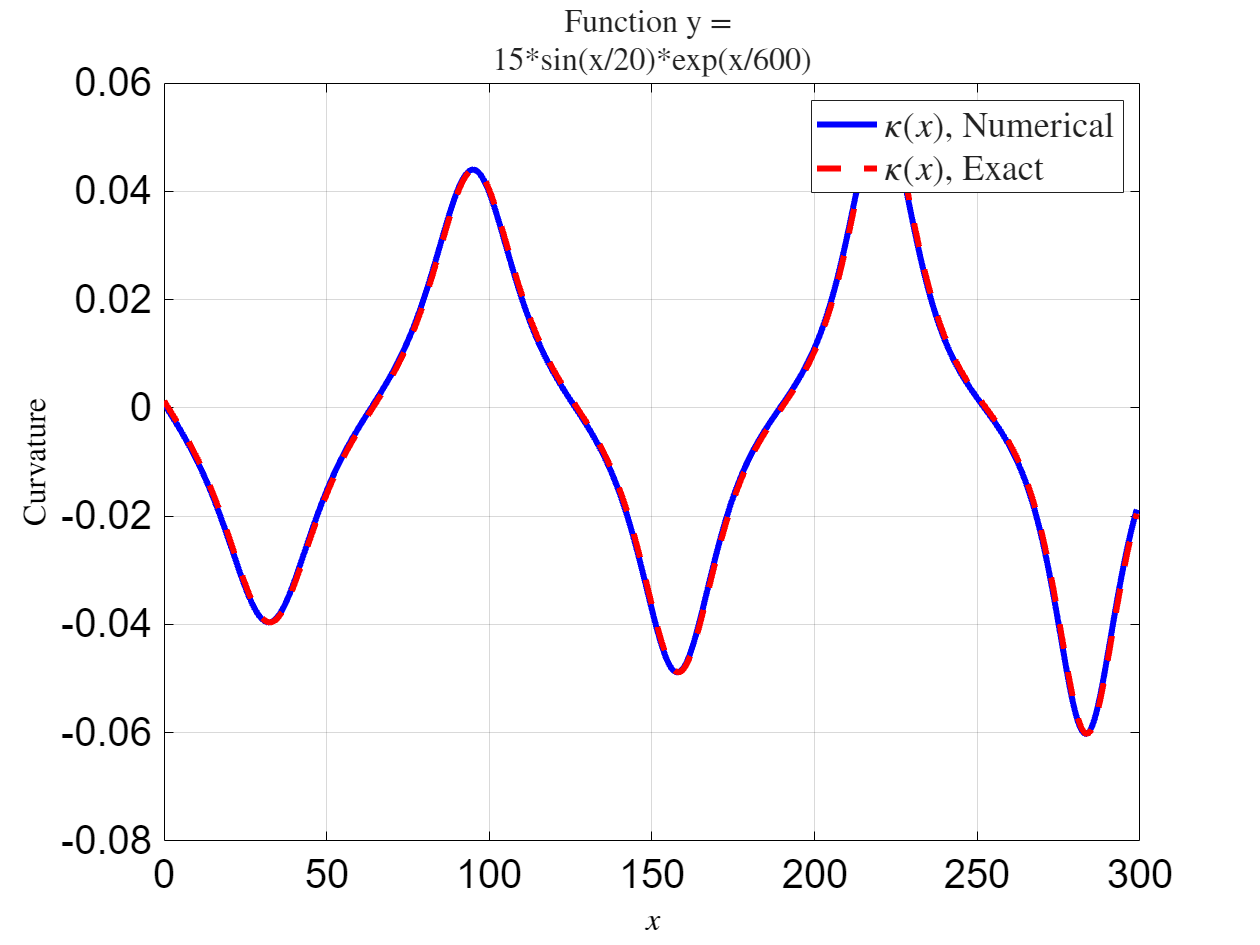

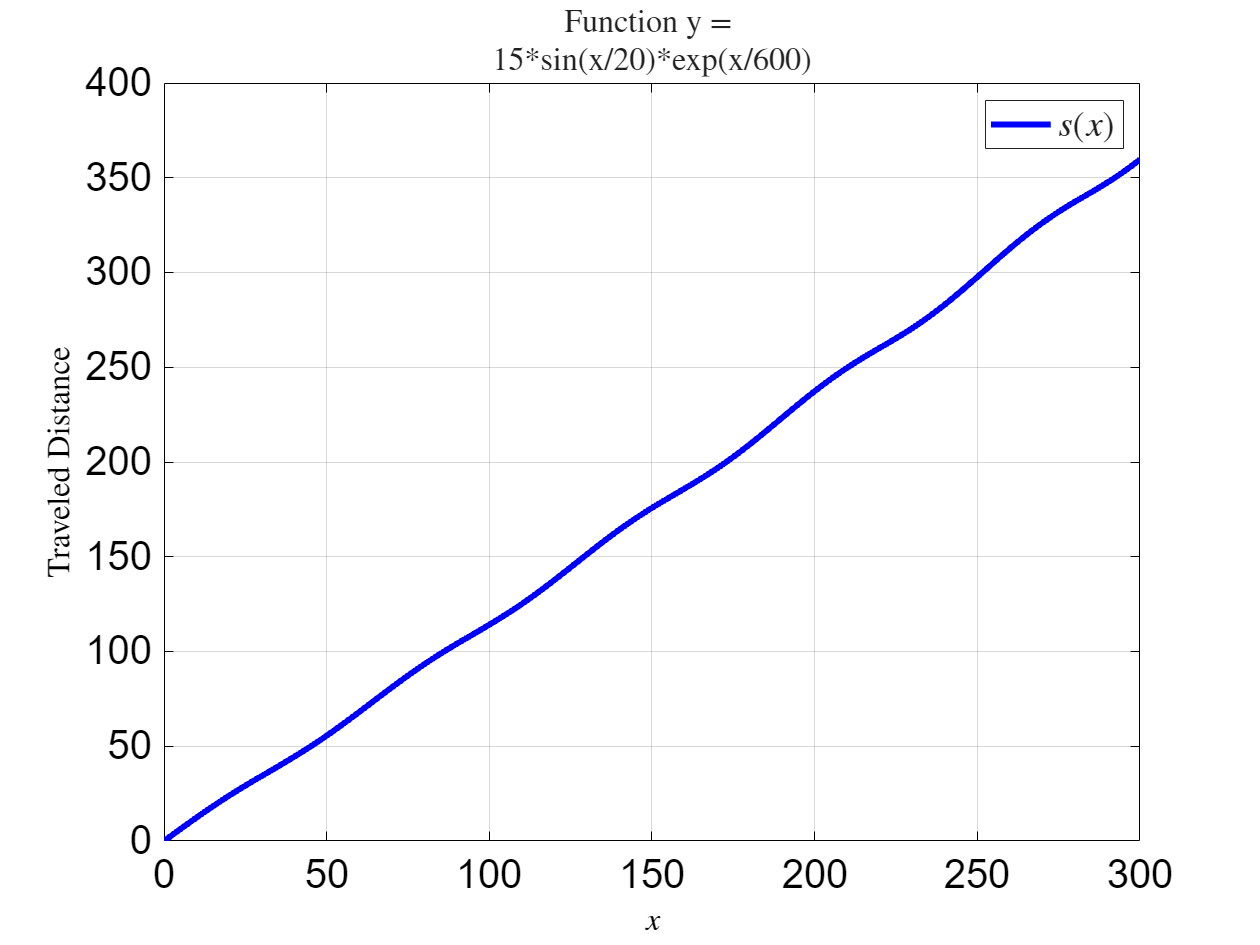

clear; % Clear workspace to start fresh

%% Symbolic Road Definition
% Define symbolic variables and road function
syms x; % Symbolic variable for x-coordinate
y = 15 * sin(0.05 * x) * exp(x/600); % Example road function: y = sin(x)
road_xLength = 300; % Length of the road in x-direction (meters)

%% Road Settings
% Trajectory Generation
numberOfLines = 4;      % Number of lanes
lineWidth = 4;          % Width of each lane (meters)
functionBasedFlag = 1;  % Use function-based calculations (1 = true for symbolic)
roadType = 'symbolic';  % Road type: 'symbolic' (uses mathematical function)
dx = 0.5;              % Spatial resolution for x-vector (meters)
plotFlag = 'yes';       % Plotting option: 'yes' to visualize curvature, 'no' to skip

% Instantiate roadMaker object with symbolic road
roadClass = roadMaker(roadType, numberOfLines, lineWidth, functionBasedFlag, dx, plotFlag, road_xLength, x, y);

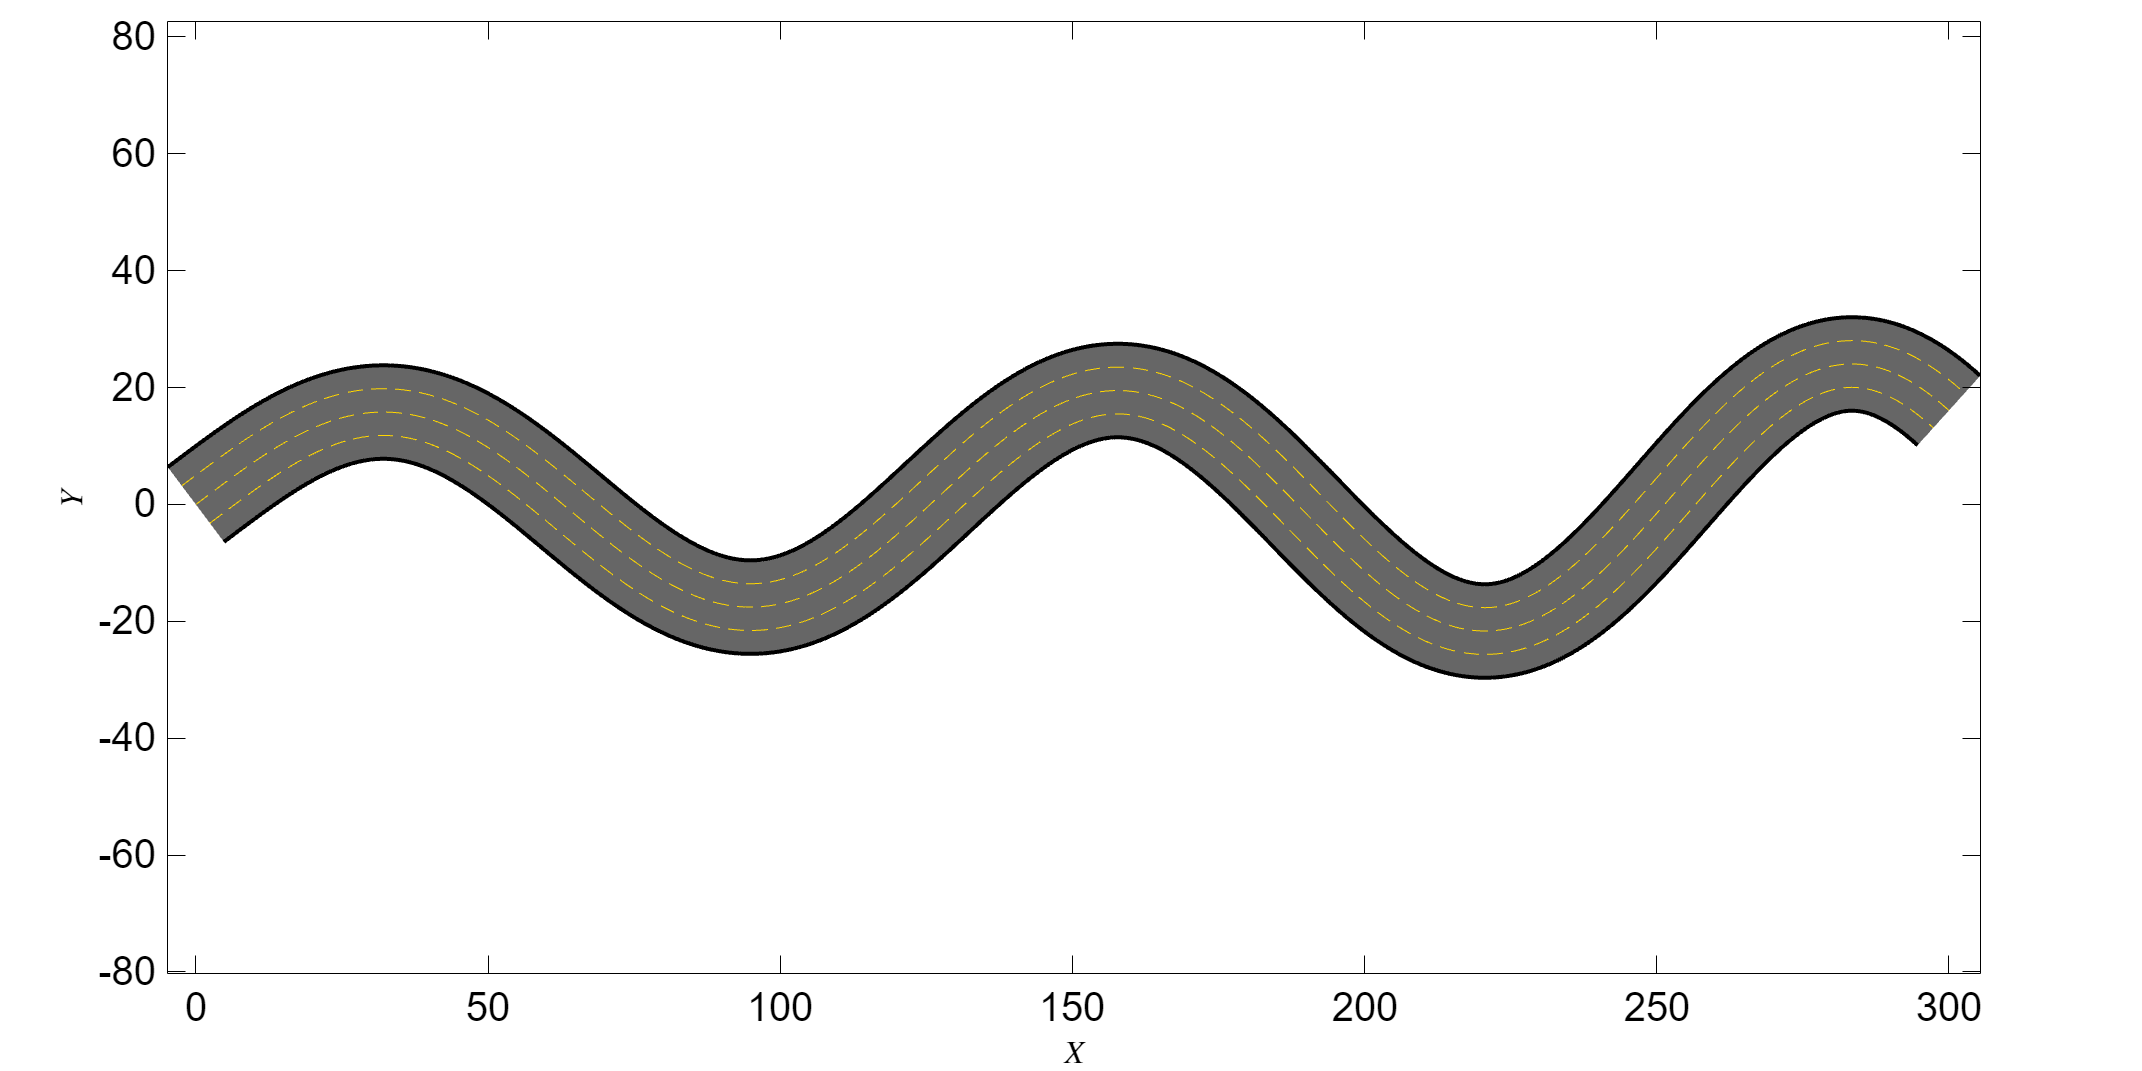


%% Visualization and Processing
% Plot the road trajectory with lanes
roadClass.plotRoad();


% Precompute interpolants for later use (e.g., waypoint generation)
interpolantSetup = roadClass.precomputeInterpolants();

% Optional: Check curvature criticality
% roadClass.checkCurvature();

%% Notes
% - rng(2025) can be uncommented if reproducible random numbers are needed (e.g., for waypoints).
% - plotFlag = 'yes' generates curvature and arc length plots automatically for symbolic roads.
% - No geographic animation (animateRoute) since this is a symbolic road in Cartesian space.